omega_0 = 30;
K= 250;
b_f=1;
m_e = 1;
I_t = 0.03;
b_e = 0;
k_e = 300;
%eval(eqn_set)
[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys=tf([numa],[dena(1) dena(2) 0 dena(3) 0]);
%Z=tf([1 20 100],[100 0])
w = logspace(-2,4,200)

w = 	1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


[re,im,freq] = nyquist(sys,w);
syms w
syms(w,'real');
s=j*w

$$s = w\,\mathrm{i}$$

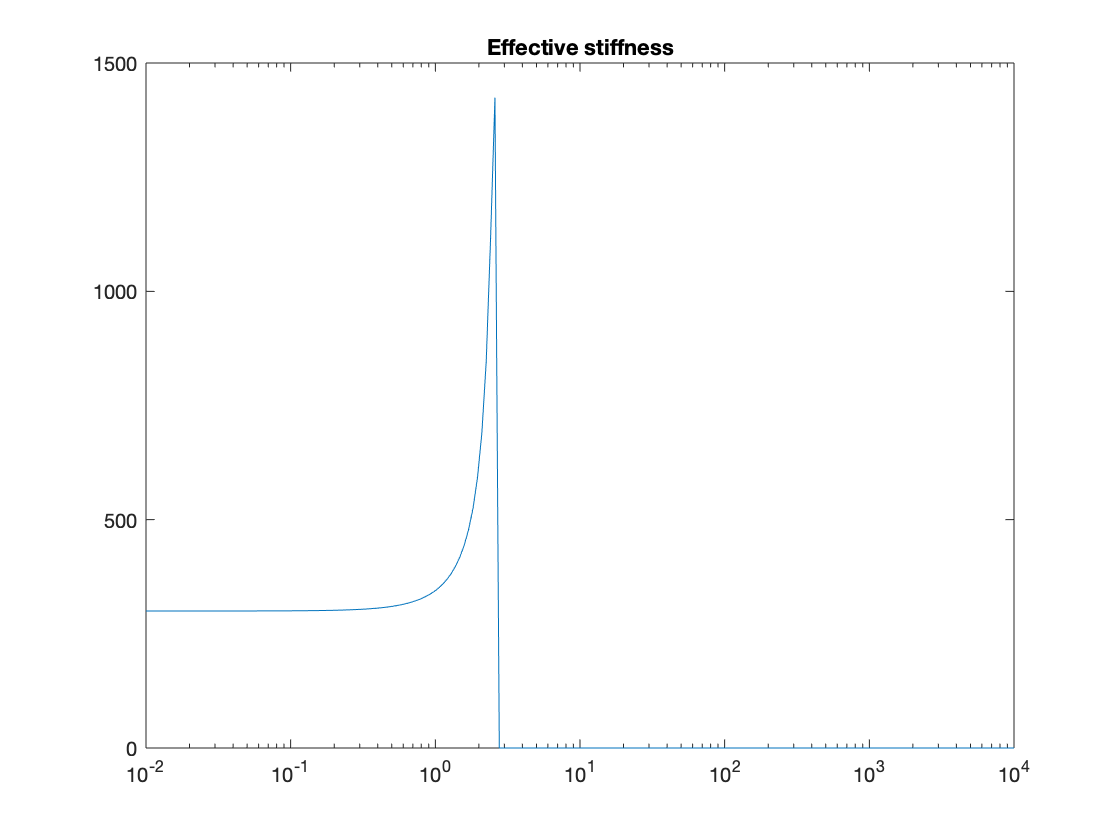

%Z2=(s^2+20*s+100)/(100*s)
%Z2=eval(Z2)
im_pos_index=find(( im>0 ));
im_neg_index=find(( im<0 ));
re_pos_index=find(( re>0 ));
re_neg_index=find(( re<0 ));
ES=[]; EM=[]; ED=[]; EIF=[];
for i=1:length(freq)
    if any(im_neg_index==i)
    ES(i)=-freq(i)*im(:,:,i);
    else
    ES(i)=0;
    end
end
for i=1:length(freq)
    if any(im_pos_index==i)
    EM(i)=freq(i)^-1*im(:,:,i);
    else
    EM(i)=0;
    end
end
for i=1:length(freq)
    if any(re_pos_index==i)
    ED(i)=re(:,:,i);
    else
    ED(i)=0;
    end
end
for i=1:length(freq)
    if any(re_neg_index==i)
    EIF(i)=freq(i)^2*re(:,:,i);
    else
    EIF(i)=0;
    end
end
plot(freq,ES)
set(gca, 'XScale', 'log')
title('Effective stiffness')

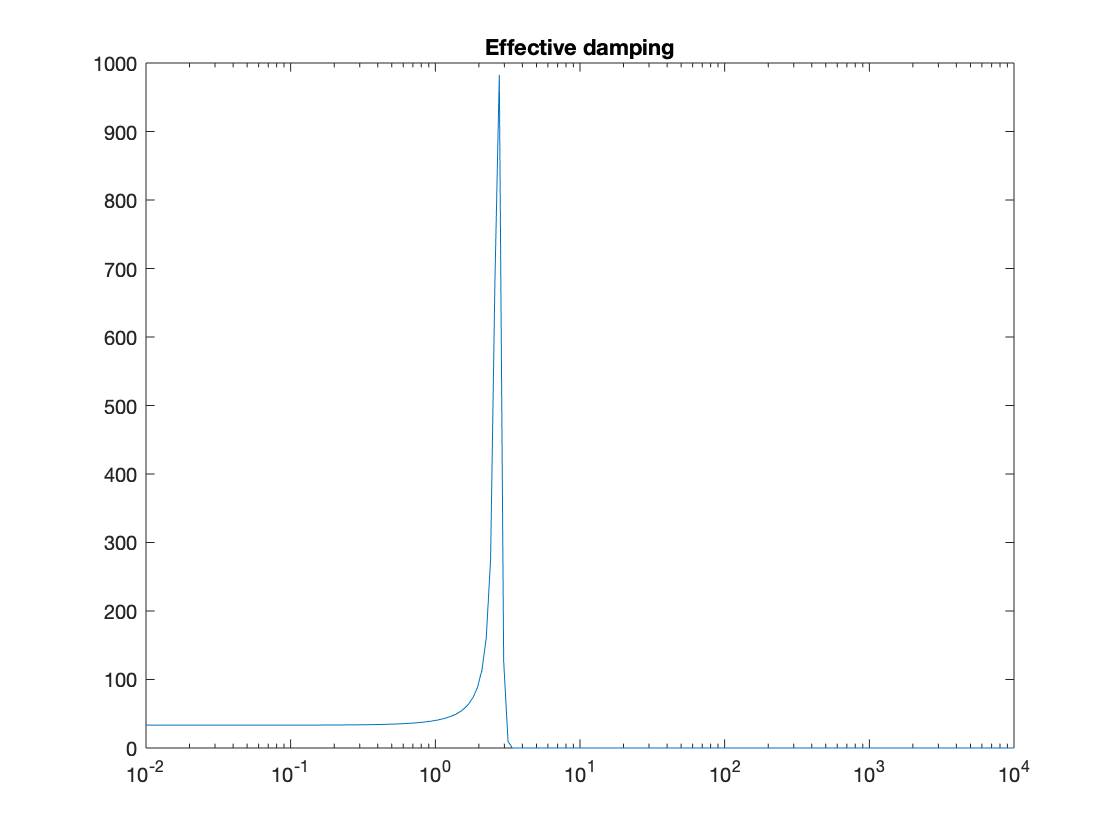

plot(freq,ED)
set(gca, 'XScale', 'log')
title('Effective damping')

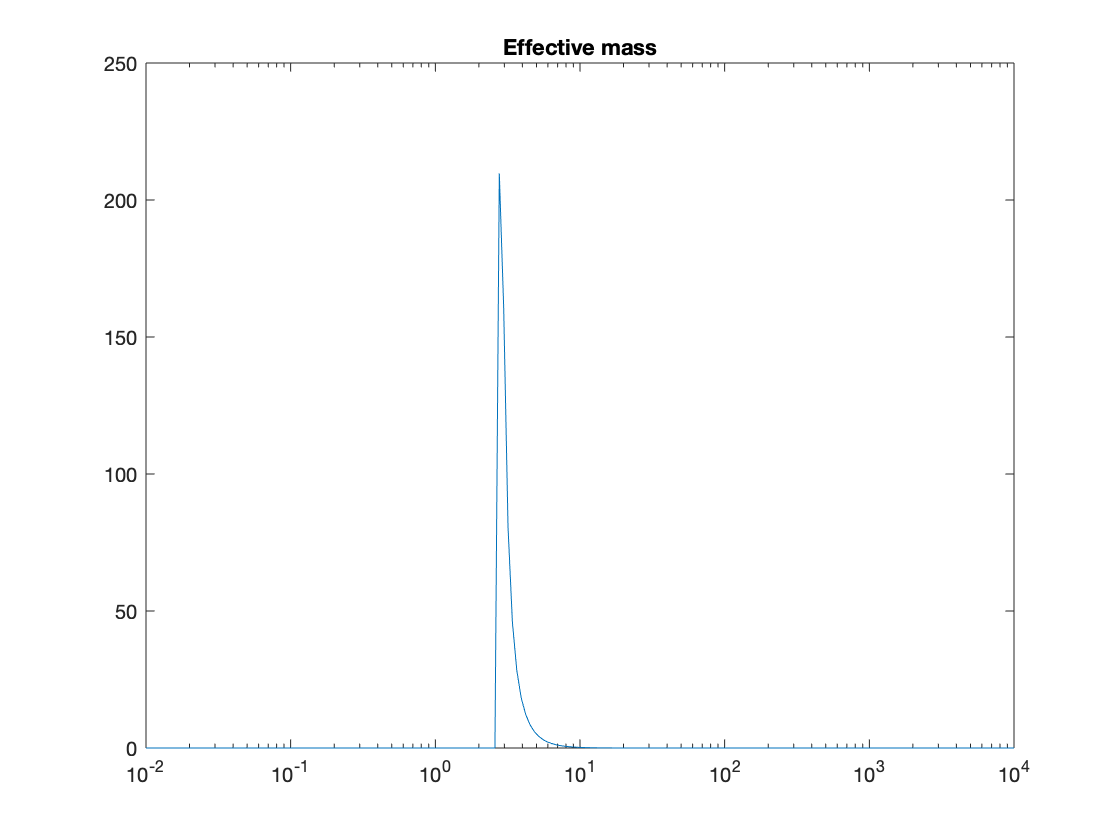

plot(freq,EM)
set(gca, 'XScale', 'log')
title('Effective mass')

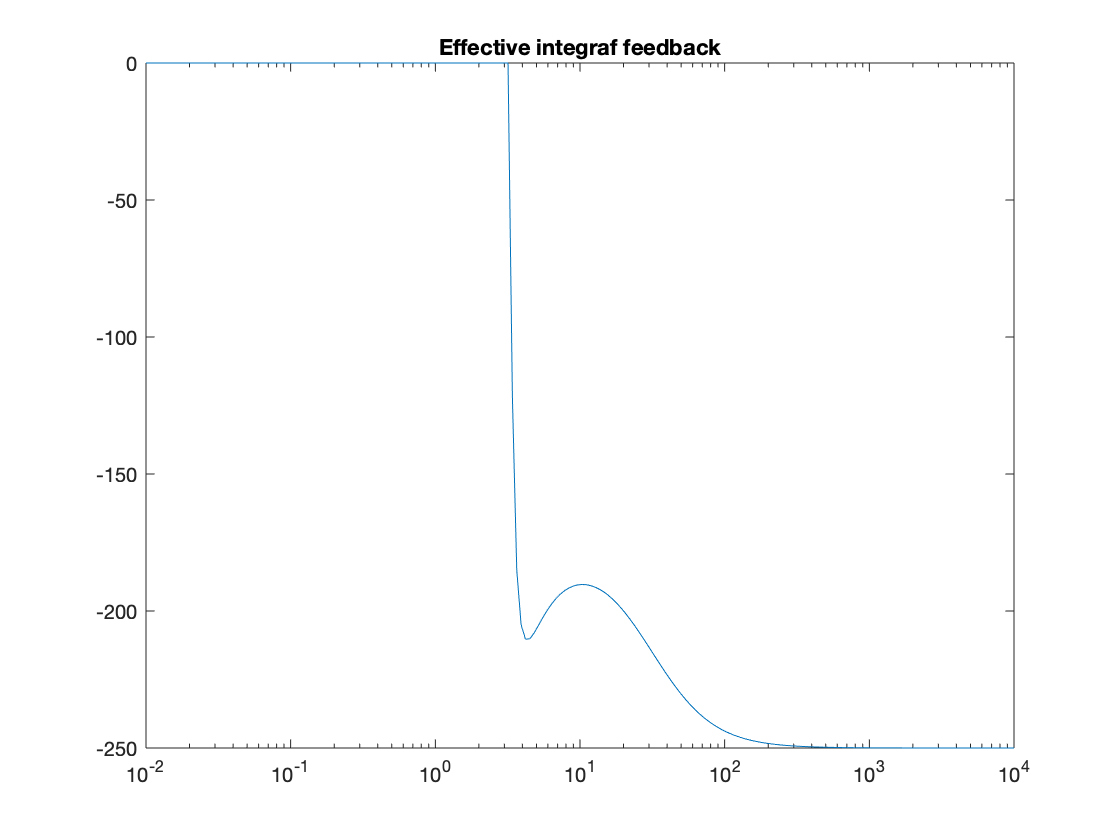

plot(freq,EIF)
set(gca, 'XScale', 'log')
title('Effective integraf feedback')

clear s; syms s
phy=tf([K],[1, 0]);
%[nume dene]=numden((Y_e));
nume=[1 0];
dene=[I_t b_e k_e] %eval(fliplr(coeffs(dene,s)));

dene =     0.0300         0  300.0000


env=tf(nume,dene);
zenv=tf(dene,[1 0])


zenv =
 
  0.03 s^2 + 300
  --------------
        s
 
Continuous-time transfer function.



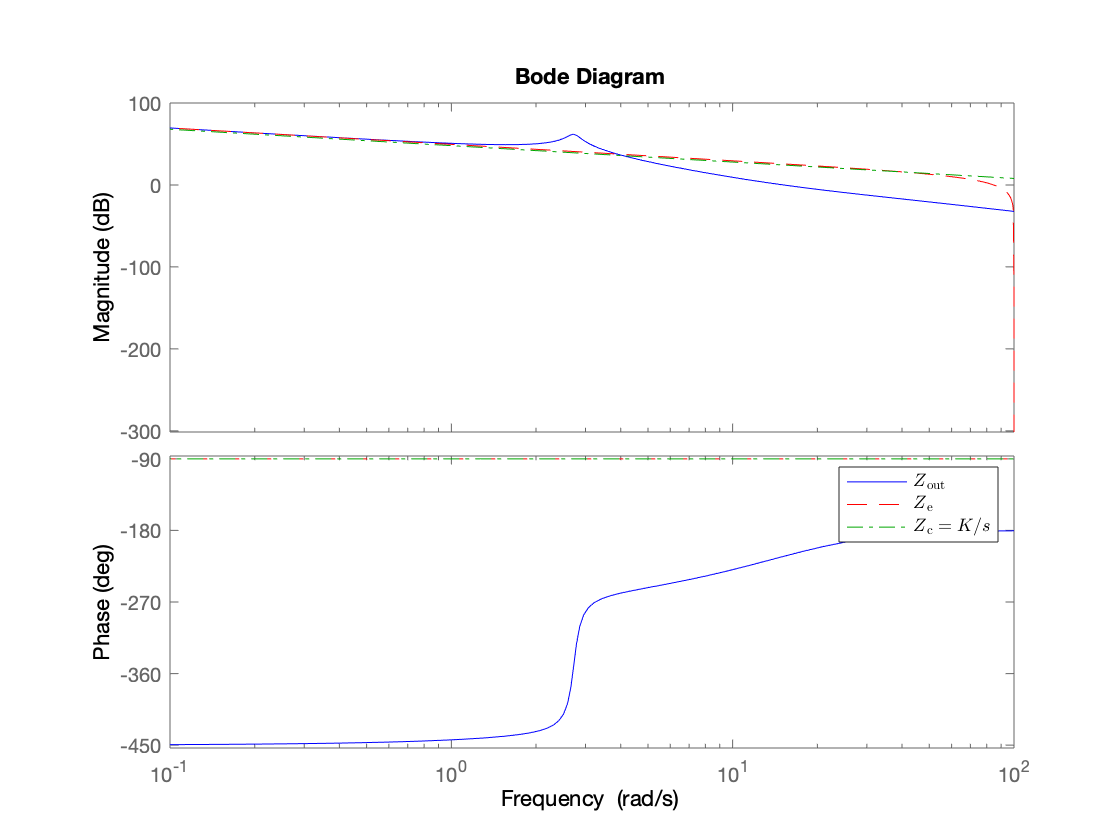


% Normal below
bode(sys,'b-',zenv,'r--',phy,'g-.',{0,100}) 
h = legend('$Z\_{\mathrm{out}}$', '$Z\_{\mathrm{e}}$', '$Z\_{\mathrm{c}}=K/s$'); set(h, 'Interpreter', 'latex');